%Seed

clc
seed = 123123745;
rng(seed)

nrows = 1300;
ncols = 1300;

obstacles = false(nrows,ncols);

[x, y] = meshgrid(1:ncols, 1:nrows);

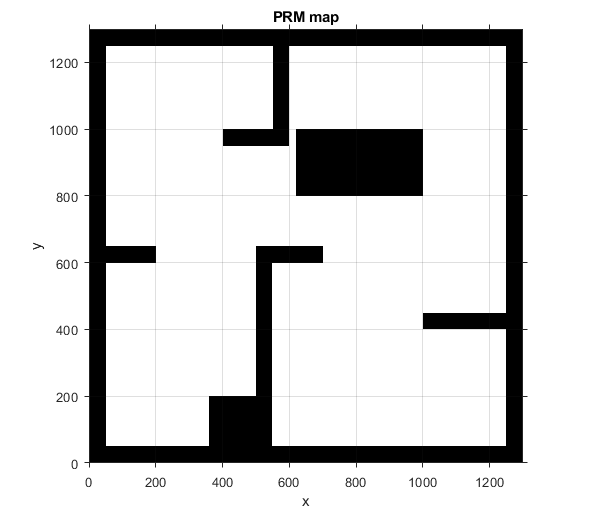

obstacles (y<50 | y>1250 | x<50 | x>1250) = true;
obstacles (y<650 & y>600 & x<200) = true;
obstacles (y<1000 & y>800 & x<1000 & x>620) = true;
obstacles (y<650 & x>500 & x<550) = true;
obstacles (y<650 & y>600 & x<700 & x>500) = true;
obstacles (y<200 & x>360 & x<550) = true;
obstacles (y>1000 & x>550 & x<600) = true;
obstacles (y<1000 & y>950 & x<600 & x>400) = true;
obstacles (y<450 & y>400 & x>1000) = true;



figure;
imshow(~obstacles);

axis ([0 ncols 0 nrows]);
axis xy;
axis on;
xlabel('x');
ylabel('y');

title('PRM map');
grid on

% n = num of sampling points
n = 10;
start = [200,200];
goal = [800,1100];

L = norm(goal-start)

L = 1.0817e+03


y_diff = abs(goal(2) - start(2));
x_diff = abs(goal(1) - start(1));
% theta = pi/2 - atan(y_diff/x_diff);
theta = atan(y_diff/x_diff);

% y_diff = goal(2) - start(2);
% x_diff = goal(1) - start(1);
% theta = atan2(y_diff,x_diff);

Nd = L/(n+1)

Nd = 98.3332

% yy = y_diff/n
% xx = x_diff/n
% z = norm([xx,yy])
% Ndx = z;%L/n;
% Ndy = z;%L/n;

% N  - number of sample in each sampling layer
%N = 30

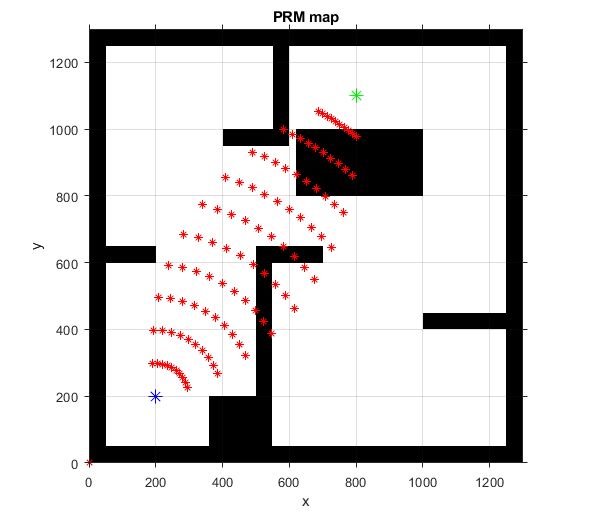

% phi_m - maximum defelction angle (45 deg)
% phi_j - angle of deflection of sampling point
points_btw = zeros(n*N,2);
g=1;
phi_m = 40;
delta_phi = phi_m/n;
% phi_list = zeros(1,n);
% phi_list(1) = -phi_m;
% for i = 1:n-1
%     phi_list(i+1) = -phi_m + (2 * i * delta_phi);
% end

phi_list = linspace(-phi_m,phi_m,n);
see = zeros(n-1,n);
for i = 1:n
    rd = i*Nd;
%     rdx = i * Ndx;
%     rdy = i * Ndy;
    see(i,:) = phi_list;
    for j = 1:n
        phi_j = phi_list(j) * pi/180;%(-phi_m + randi(2*phi_m)) * pi/180;
        x = start(1) + rd*cos(theta + phi_j);
        y = start(2) + rd*sin(theta + phi_j);
%         x = start(1) + rdx*cos(theta + phi_j);
%         y = start(2) + rdy*sin(theta + phi_j);
        points_btw(g,1) = x;
        points_btw(g,2) = y;
        g=g+1;
    end
%     if i > floor(n/2-1)
%         phi_m = phi_m - delta_phi;
%     else
%         phi_m = phi_m + delta_phi;
%     end
    phi_m = phi_m - delta_phi;
    
    phi_list = linspace(-phi_m,phi_m,n);
end

%points_btw
hold on
plot(start(1),start(2),'b*','MarkerSize',10);
plot(goal(1),goal(2),'g*','MarkerSize',10);
hold off
for i = 1:numel(points_btw(:,1))
    hold on
%     if (Nodes == 0 || Nodes == 1)
%         plot(Node_X,Node_Y,'g*','MarkerSize',10);
%     else
    plot(points_btw(i,1),points_btw(i,2),'r*');
    %end
    hold off
end